### Process the OTOC data and extract the MQC intensities

Code last modified by Yuchen Li, 2023-9-19.

clc;clear

#### At first, I process the oscillating case, of which the Hamiltonian configuration is $\xi =\left(-0\ldotp 1,0\ldotp 1,0\right)\ldotp$

load S1.mat
load S1_uncertainty.mat

load J1.mat %The calibration results of J
load J1_uncert.mat

xi_1=-0.1;
xi_2=0.1;

W_x=-6*xi_1*xi_2; 

tau=5*1e-6; %in us

td2=31;
quench_time=(0:td2-1)*24*tau*1e3; 
J_bar=mean(J1_seq,"all")*1e-3; %in ms

td1=33;
phi=(0:(td1-1))*2*pi/(td1);
figure()
plot(phi/2/pi,S(1:2:31,:))
xlabel('Rotation angle (*2\pi)')
ylabel('$F(t,\phi)$','Interpreter',"latex",'fontsize',12)
title(['$\xi=[-0.1,0.1,0], A=',num2str(A),'$, $\mathrm{tr}[\exp(-iI_z\phi)I_z(t)\exp(iI_z\phi)I_z(t)]$'],'Interpreter',"latex",'fontsize',11)
legend(['t=',num2str(quench_time(1))],['t=',num2str(quench_time(3))],['t=',num2str(quench_time(5))],...
    ['t=',num2str(quench_time(7))],['t=',num2str(quench_time(9))],['t=',num2str(quench_time(11))],...
    ['t=',num2str(quench_time(13))],['t=',num2str(quench_time(15))],'box','off')

color={[157 195 231]/255
[196 151 178]/255
[169 184 198]/255
[150 195 125]/255
[243 120 102]/255
    };

L=td1-1;
Y=real(fft(S,L,2))/L;
mqc=[Y(:,1),2*Y(:,2:L/2)];
std_zeroorder=(mean(FID_uncertainty,2))/L^0.5;
std_otherorder=2*(mean(FID_uncertainty,2))/(2*L)^0.5;

mqc_order=0:L/2-1;
figure()
pick_num=[1:3:13];
for i=1:length(pick_num)
    subplot(length(pick_num),1,i)
    bar(mqc_order,mqc(pick_num(i),:),0.5,'FaceColor',color{1})
    title(['$\bar{J}t=',num2str(round(J_bar*quench_time(pick_num(i)),2)),'$'],'Position',[5,0.4],'Interpreter','latex')
    xlim([-1 7])
    ylim([0 1])
    yticks([0 0.5 1])
    xticklabels({});
    if i==length(pick_num)
        xticks(-1:1:10)
        xtickangle(0)
        xticklabels({'','0','','2','','4','','6','','8','','10'})
    end
    box off
end
xlabel('MQC order $|m|$','Interpreter','latex')
ylabel('MQC intensity $I_m$','Interpreter','latex')
fontsize(gcf,8,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,4,6]); 
set(gca,'XTickLabelRotation',0)
saveas(gcf,'d.pdf')

figure()
marker={'.-','-^','-s','-d','-v','.-','-d','-s','-^','-x'};
markersize=[8,1.6,2,2,1.6,8,2,2,2,2,2]*0.8;
% color={'#0072bd','#D95319','#eDb120','#7e2f8e','#77ac30','#eDb120','#7e2f8e','#77ac30','#eDb120','#7e2f8e','#77ac30'};
color={  [157 195 231]/255
    [196 151 178]/255
    [243 210 102]/255
[169 184 198]/255
[150 195 125]/255
    };
select=[1:31];

figure()
error_bar=std_zeroorder;
b=errorbar(quench_time(select)*J_bar,mqc(select,1),error_bar,marker{1},'MarkerSize',markersize(1),'MarkerFaceColor',color{1},'capsize',0);
b.Color=color{1};
hold on
for i=2:5
    error_bar=std_otherorder;
    b=errorbar(quench_time(select)*J_bar,mqc(select,2*i-1),error_bar,marker{i},'MarkerSize',markersize(i),'MarkerFaceColor',color{i},'capsize',0);
    b.Color=color{i};
end

xlabel('$\bar{J}t$','Interpreter','latex')
ylabel('MQC intensity')

% legend('$|m|=0$','$|m|=2$','$|m|=4$','$|m|=6$',['$|m|' ...
%     '=8$'],'interpreter','latex','box','off','FontSize',15)
xlim([0 5])
xticks(0:2:6)
ylim([-0.02 1])
yticks(0:0.2:1)
yticklabels({'0','0.2','0.4','0.6','0.8','1'})

fontsize(gcf,8,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,4,5.5]); 
set(gca,'XTickLabelRotation',0)
saveas(gcf,'b.pdf')

#### Next I process the non-oscillating case, of which the Hamiltonian configuration is $\xi =\left(-0\ldotp 125,-0\ldotp 025,0\ldotp 15\right)\ldotp$

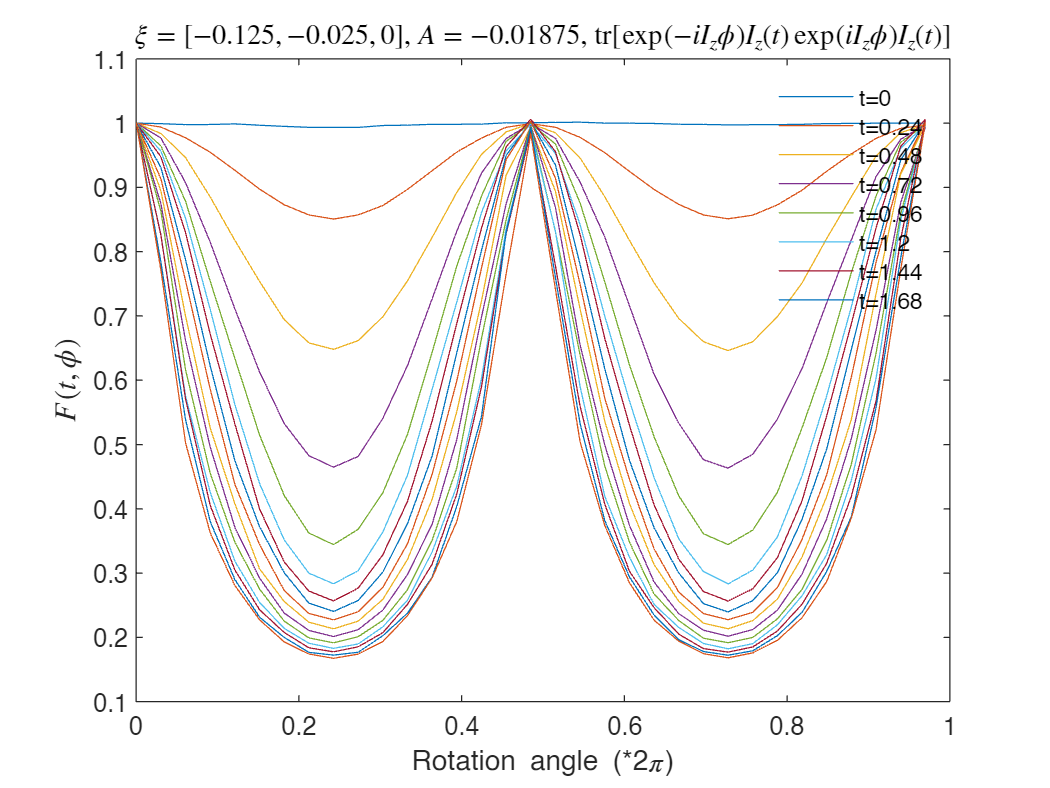

load S2.mat
load S2_uncertainty.mat

load J1.mat     %The calibration results of J
load J1_uncert.mat

xi_1=-0.125;
xi_2=-0.025;
A=-6*xi_1*xi_2;

tau=5*1e-6; %in us

td2=31;
quench_time=(0:td2-1)*24*tau*1e3;
td1=33;
phi=(0:(td1-1))*2*pi/(td1);
figure()
plot(phi/2/pi,S(1:2:31,:))
xlabel('Rotation angle (*2\pi)')
ylabel('$F(t,\phi)$','Interpreter',"latex",'fontsize',12)
title(['$\xi=[-0.125,-0.025,0], A=',num2str(A),'$, $\mathrm{tr}[\exp(-iI_z\phi)I_z(t)\exp(iI_z\phi)I_z(t)]$'],'Interpreter',"latex",'fontsize',11)
legend(['t=',num2str(quench_time(1))],['t=',num2str(quench_time(3))],['t=',num2str(quench_time(5))],...
    ['t=',num2str(quench_time(7))],['t=',num2str(quench_time(9))],['t=',num2str(quench_time(11))],...
    ['t=',num2str(quench_time(13))],['t=',num2str(quench_time(15))],'box','off')

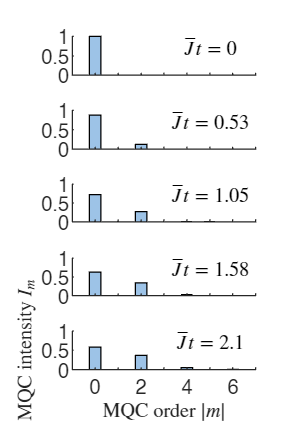

L=td1-1;
Y=real(fft(S,L,2))/L;
mqc=[Y(:,1),2*Y(:,2:L/2)];
std_zeroorder=(mean(FID_uncertainty,2))/L^0.5;
std_otherorder=2*(mean(FID_uncertainty,2))/(2*L)^0.5;

mqc_order=0:L/2-1;
figure()
pick_num=[1:3:13];
for i=1:length(pick_num)
    subplot(length(pick_num),1,i)
    bar(mqc_order,mqc(pick_num(i),:),0.5,'FaceColor',color{1})
    title(['$\bar{J}t=',num2str(round(J_bar*quench_time(pick_num(i)),2)),'$'],'Position',[5,0.4],'Interpreter','latex')
    xlim([-1 7])
    ylim([0 1])
    xticklabels({});
    if i==length(pick_num)
        xticks(-1:1:10)
        xtickangle(0)
        xticklabels({'','0','','2','','4','','6','','8','','10'})
    end
    box off
end
xlabel('MQC order $|m|$','Interpreter','latex')
ylabel('MQC intensity $I_m$','Interpreter','latex')
fontsize(gcf,8,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,4,6]); 
set(gca,'XTickLabelRotation',0)
saveas(gcf,'c.pdf')

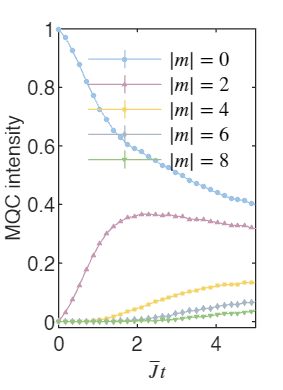

figure()
marker={'.-','-^','-s','-d','-v','.-','-d','-s','-^','-x'};
markersize=[8,1.6,2,2,1.6,8,2,2,2,2,2]*0.8;
% color={'#0072bd','#D95319','#eDb120','#7e2f8e','#77ac30','#eDb120','#7e2f8e','#77ac30','#eDb120','#7e2f8e','#77ac30'};
select=[1:31];
figure()
error_bar=std_zeroorder;
b=errorbar(quench_time(select)*J_bar,mqc(select,1),error_bar,marker{1},'MarkerSize',markersize(1),'MarkerFaceColor',color{1},'capsize',0);
b.Color=color{1};
hold on
for i=2:5
    error_bar=std_otherorder;
    b=errorbar(quench_time(select)*J_bar,mqc(select,2*i-1),error_bar,marker{i},'MarkerSize',markersize(i),'MarkerFaceColor',color{i},'capsize',0);
    b.Color=color{i};
end

xlabel('$\bar{J}t$','Interpreter','latex')
ylabel('MQC intensity')
legend('$|m|=0$','$|m|=2$','$|m|=4$','$|m|=6$',['$|m|' ...
    '=8$'],'interpreter','latex','box','off')
xlim([0 5])
xticks(0:2:6)
ylim([-0.02 1])
yticks(0:0.2:1)
yticklabels({'0','0.2','0.4','0.6','0.8','1'})

fontsize(gcf,8,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,4,5.5]); 
set(gca,'XTickLabelRotation',0)
saveas(gcf,'a.pdf')